clear;clc;

## Hydrodynamic Coefficient from WAMIT

LUPA_width = 1;
D_space = LUPA_width*4;
%filename=fprintf('hydro/2WEC_Spacing_4p00m.h5',D_space);
filename='hydro/2WEC_Spacing_4p00m.h5';
hydro = convh5_v2(filename);

C_f1 = hydro.float_up.dry_mass+squeeze(hydro.float_up.Add_mass(3,3,:))';
L_hs_f1 = 1./hydro.float_up.K(3,3);
R_rad_f1 = 1./squeeze(hydro.float_up.Rad_damping(3,3,:))';
Fex_f1 = squeeze(complex(hydro.float_up.Fex_re,hydro.float_up.Fex_im));

C_f2 = hydro.float_dn.dry_mass+squeeze(hydro.float_dn.Add_mass(3,15,:))';
L_hs_f2 = 1./hydro.float_dn.K(3,3);
R_rad_f2 = 1./squeeze(hydro.float_dn.Rad_damping(3,15,:))';
Fex_f2 = squeeze(complex(hydro.float_dn.Fex_re,hydro.float_dn.Fex_im));


## Excitation Force Analysis

% phase_shift_WECs = (angle(Fex_f1) - angle(Fex_f2))
% 
% plot(hydro.w,phase_shift_WECs/2/pi*360)
% 
% %% Fex Validation
% figure (1)
% subplot(2,1,1)
% hold on
% plot(hydro.w,real(Fex_f1(3,:)))
% plot(hydro.w,real(Fex_f2(3,:)))
% hold off
% xlabel("Frequency (rad/s)")
% ylabel("Excitation Force Vector (N)")
% legend("upstream","downstream")
% title("Real component")
% subplot(2,1,2)
% hold on
% plot(hydro.w,imag(Fex_f1(3,:)))
% plot(hydro.w,imag(Fex_f2(3,:)))
% hold off
% xlabel("Frequency (rad/s)")
% ylabel("Excitation Force Vector (N)")
% legend("upstream","downstream")
% title("Imaginary component")

## PMSM Parameter

%%Machine parameters
lambda = 0.483; %From datasheet with series connection
pp=12;
rx=75;
J=1.786e-2;
B=1/350;
Rs=5.87;
Lq=(53.60e-3/1.5);
r= 0.0636651;
radstorpm=60/(2*pi);

## Underwater Cable Parameter

A. Beddard and M. Barnes, "HVDC cable modelling for VSC-HVDC applications," *2014 IEEE PES General Meeting | Conference & Exposition*, National Harbor, MD, USA, 2014, pp. 1-5, doi: 10.1109/PESGM.2014.6939059.

*Copper resistivity is typically given as $$1.68\times10^{-8} \, \Omega/m $$. It has been increased to $$2.2\times10^{-8} \, \Omega/m $$  for the cable model due to stranded nature of the cable.

The skin depth $\(\delta\)$ quantifies the extent of the skin effect. Defined as the distance from the surface where the current density decreases to $\(e^{-1}\) (\(\approx 37\%\))$ of its surface value, it is calculated as:


$$$
\delta = \sqrt{\frac{2}{\gamma \omega \mu}},
$$$


where $\(\mu\)$ is the material permeability, $\(\omega\)$ is the angular frequency, and $\(\gamma\)$ is the electrical conductivity. The current density $\(J(r)\)$ at a depth $\(r\)$ within the conductor follows an exponential decay:


$$$

J(r) = J_0 e^{-r / \delta},
$$$


where $\(J_0\)$ is the current density at the conductor surface.

For conductors with a radius $\(R_\mathrm{c}\)$ exceeding $\(\delta\)$, integrating $\(J(r)\)$ reveals that approximately $$ 86\ \%$$ of the total current flows within the skin depth, while $$14\ \%$$ is distributed deeper inside the conductor. However, for typical power transmission lines using copper at 60 Hz, $\(\delta \approx 8.5 \, \mathrm{mm}\)$, which exceeds the radius of most conductors in practical use. Thus, the assumption $\(R_\mathrm{c} < \delta\)$ holds, and the current density can be approximated as uniform across the cross-section.

gam = 1/2.2e-8; % (Simens/m) stranded copper wire conductivity per length
mu = 1.256629e-6; %Absolute permeability H/m
Tp = 2; % 2 seconds of dominant period of wave input
omega = 2*pi/Tp; 
d_skin = sqrt(2/gam/omega/mu); % Skin Depth calculation


## Pacwave Site Grid Scaling

sc_factor = 1/20;
A = 24.9e-6*sc_factor^2 ; % Radial thickness of the stranded copper wire 
D_spacing = 4; % Distance between WEC float edges (m)
h_seabed = 70*sc_factor; % scale down seabed depth of average PacWave site
L_wire = 0.5 * D_spacing + h_seabed; % Cable length(Center to the spacing plus depth of seabed) to the power collection point
R_cable = 1/gam*L_wire/A;

R_cable_full_scale = R_cable*sc_factor;

V_Pac_Wave_AC = 12470;

V_grid_scaled_AC = V_Pac_Wave_AC *sc_factor^1.25;

V_PA_Wave_DC_eqk = V_Pac_Wave_AC*sqrt(2)*1.2;

V_grid_scaled = V_PA_Wave_DC_eqk *sc_factor^1.25;

% 
% f_Grid = 60 ; % 60 Hz
% f_scaled = f_Grid * sc_factor^(-0.5);



## Sankey Diagram

Incident Wave Power

 ├─→ Absorbed (WEC1)

 │     └─→ PTO (WEC1)

 │           ├─→ Delivered Power (WEC1)

 │           └─→ Electrical Loss (WEC1)

 ├─→ Absorbed (WEC2)

 │     └─→ PTO (WEC2)

 │           ├─→ Delivered Power (WEC2)

 │           └─→ Electrical Loss (WEC2)

 └─→ Not Absorbed (passes by / scattered)

The Sankey diagram illustrates the average power flow from the incident wave field to the electrical delivery point. Incident wave power is partially absorbed by the WEC due to hydrodynamic coupling and phase effects between excitation force and body velocity. The absorbed power is converted by the PTO, after which electrical transmission losses are incurred. The remaining incident wave power passes the device without being absorbed.

out=sim("LUPA_Array_Eqk_circuit_w_PTO_DC_link_v2.slx");

Found algebraic loop that contains: 
LUPA_Array_Eqk_circuit_w_PTO_DC_link_v2/V_ctrl_pto1/Product
LUPA_Array_Eqk_circuit_w_PTO_DC_link_v2/Solver Configuration/EVAL_KEY/INPUT_2_1_1
LUPA_Array_Eqk_circuit_w_PTO_DC_link_v2/Solver Configuration/EVAL_KEY/STATE_1 (discontinuity)
LUPA_Array_Eqk_circuit_w_PTO_DC_link_v2/Solver Configuration/EVAL_KEY/OUTPUT_1_0


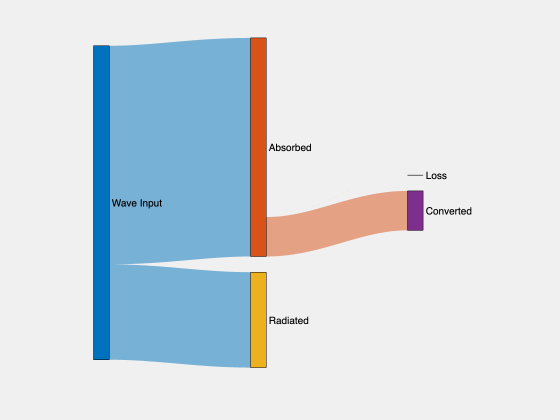

data = out.logsout;
output = struct();

for ii = 1:data.numElements
    elem = data.get(ii);                    % Simulink.SimulationData.Signal
    sigName = matlab.lang.makeValidName(elem.Name);

    % elem.Values is usually a timeseries
    output.(sigName).ts = elem.Values;      % store full timeseries object
    % Optionally also store raw arrays:
    output.(sigName).t  = elem.Values.Time;
    output.(sigName).x  = elem.Values.Data;
end


rho=1000;
g=9.81;
Hs= output.Hs.x;
Te= (2*pi/output.wp.x);

% Potential average wave power (available Power)
P_wave_input_avg = rho*g^2*Hs^2*Te/32/pi*LUPA_width;

% Average tranmitted power From Incident wave to WEC device (partially
% dissipated due to the lag between exictation force and WEC motion.)
Pin1_avg = mean(output.P_in_WEC1.x);
Pin2_avg = mean(output.P_in_WEC2.x);

% PTO generated power
PTO1_avg = mean(output.P_pto_WEC1.x);
PTO2_avg = mean(output.P_pto_WEC2.x);

% Local Transmission losses
Loss1_avg = -mean(output.P_loss_WEC1.x);
Loss2_avg = -mean(output.P_loss_WEC2.x);


## example

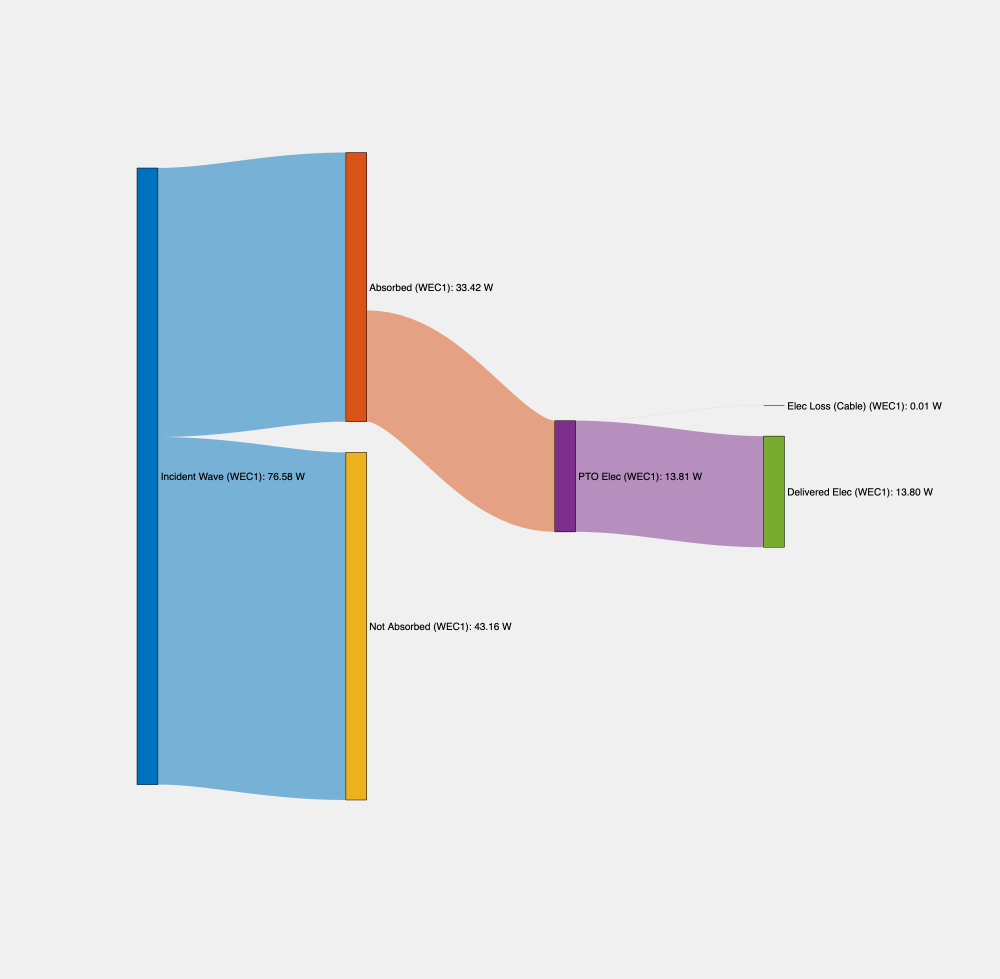

%% --- 1) Formatting helpers ---
fmtW = @(x) sprintf('%.2f W', x);  % assume W internally

%% --- 2) Build WEC1 Sankey (independent input) ---
P_inc_1   = max(P_wave_input_avg, 0);
P_abs_1   = max(Pin1_avg, 0);
P_not_1   = max(P_inc_1 - P_abs_1, 0);

P_pto_1   = max(PTO1_avg, 0);
P_loss_1  = max(Loss1_avg, 0);
P_del_1   = max(P_pto_1 - P_loss_1, 0);

N1_inc  = "Incident Wave (WEC1): "        + fmtW(P_inc_1);
N1_abs  = "Absorbed (WEC1): "             + fmtW(P_abs_1);
N1_not  = "Not Absorbed (WEC1): "         + fmtW(P_not_1);
N1_pto  = "PTO Elec (WEC1): "             + fmtW(P_pto_1);
N1_del  = "Delivered Elec (WEC1): "       + fmtW(P_del_1);
N1_loss = "Elec Loss (Cable) (WEC1): "    + fmtW(P_loss_1);

EndNodes = [
    N1_inc,  N1_abs;
    N1_inc,  N1_not;
    N1_abs,  N1_pto;
    N1_pto,  N1_del;
    N1_pto,  N1_loss;
];

Weight = [
    P_abs_1;
    P_not_1;
    P_pto_1;
    P_del_1;
    P_loss_1;
];

T1 = table(EndNodes, Weight, 'VariableNames', {'EndNodes','Weight'});
D1 = digraph(T1);

f1 = uifigure('Name','Sankey – WEC1','Position',[100 100 1000 1500]);
SC1 = SankeyChart();             % create first
SC1.Parent    = f1;
SC1.GraphData = D1;

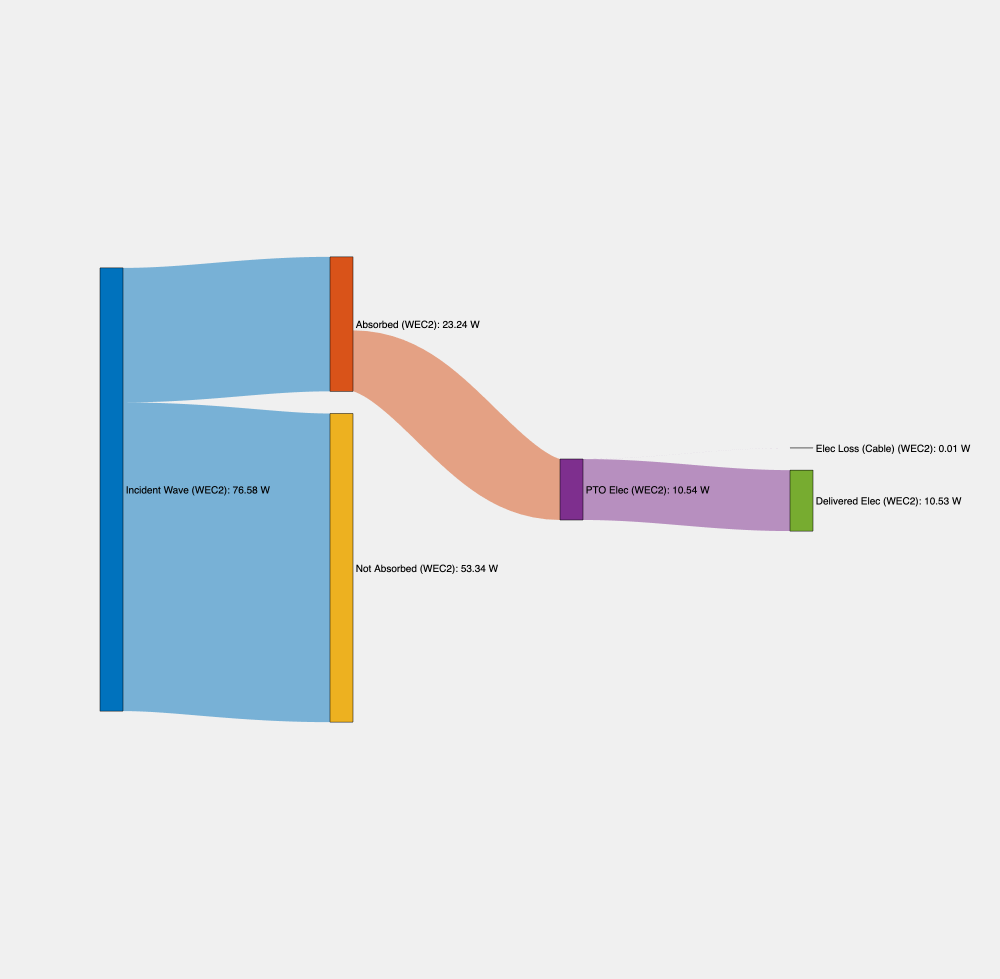


%% --- 3) Build WEC2 Sankey (independent input) ---
P_inc_2   = max(P_wave_input_avg, 0);
P_abs_2   = max(Pin2_avg, 0);
P_not_2   = max(P_inc_2 - P_abs_2, 0);

P_pto_2   = max(PTO2_avg, 0);
P_loss_2  = max(Loss2_avg, 0);
P_del_2   = max(P_pto_2 - P_loss_2, 0);

N2_inc  = "Incident Wave (WEC2): "        + fmtW(P_inc_2);
N2_abs  = "Absorbed (WEC2): "             + fmtW(P_abs_2);
N2_not  = "Not Absorbed (WEC2): "         + fmtW(P_not_2);
N2_pto  = "PTO Elec (WEC2): "             + fmtW(P_pto_2);
N2_del  = "Delivered Elec (WEC2): "       + fmtW(P_del_2);
N2_loss = "Elec Loss (Cable) (WEC2): "    + fmtW(P_loss_2);

EndNodes = [
    N2_inc,  N2_abs;
    N2_inc,  N2_not;
    N2_abs,  N2_pto;
    N2_pto,  N2_del;
    N2_pto,  N2_loss;
];

Weight = [
    P_abs_2;
    P_not_2;
    P_pto_2;
    P_del_2;
    P_loss_2;
];

T2 = table(EndNodes, Weight, 'VariableNames', {'EndNodes','Weight'});
D2 = digraph(T2);

f2 = uifigure('Name','Sankey – WEC2','position',[100 100 1000 1500]);
SC2 = SankeyChart();
SC2.Parent    = f2;
SC2.GraphData = D2;